## Objective

## Demonstrate spectral representation of Circulant Matrix

Given an $n-$dimensional 1D vector $x$  and circulant matrix $C$ , one obtains the circulant samples as a matrix-vector product $\textrm{Cx}$ . A circulant matrix is determined by its first row. Other rows are circulant shifts of the first row. In Matlab, one can call $\left.C=\textrm{gallery}{\left(\right.}^{\prime } {\textrm{circul}}^{\prime } ,x\right);$ to  generate  whose first row is $x$ . The circulant matrix has a spectral representation: $C=\left(\frac{1}{n}\right)\hat{F} *\textrm{diag}\left(\hat{F} *v\right)F$, or alternatively $C=F\;\mathrm{diag}\left(F\;v\right)\hat{F^{-1} }$ , where $F^*$  and $F$ are the Fourier transform and its adjoint, respectively, and $v$ is the first row of . This spectral representation comes from theorem below:

**Theorem**: The eigenvalues of a circulant matrix  $C\left(x\right)$ are given by the DFT,  $\;\;\overset{\Lambda }{x} \;=F\left(x\right)\;\;$and the eigenvectors by the unitary DFT matrix, $U$. Equivalently,


$$C\left(x\right)=U\;\mathrm{diag}\left(\;\;\overset{\Lambda }{x} \right)\;U^* \;$$


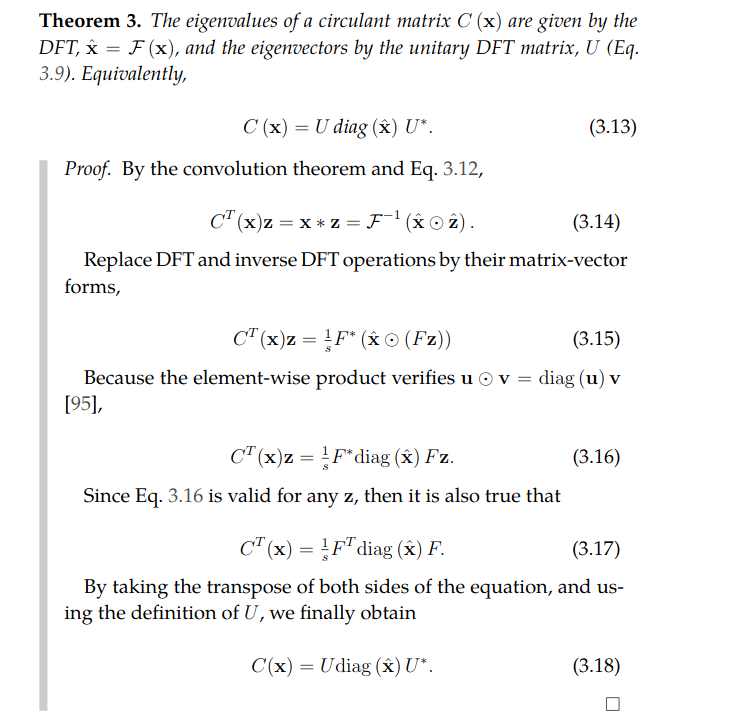

See proof on page 38 here: [https://www.robots.ox.ac.uk/~joao/publications/henriques_phd.pdf](https://www.robots.ox.ac.uk/~joao/publications/henriques_phd.pdf) 

Help was taken from this resource: [https://www.caam.rice.edu/~optimization/circulant/codes.html](https://www.caam.rice.edu/~optimization/circulant/codes.html) 

clc;
clear all;

% Generate a 1-D vector using 5 random values
x = randn(1,5);
n = length(x);

% Calculate a n-by-n complex discrete Fourier transform matrix
F = dftmtx(n);

% Generate ciculant matrix using MATLAB commands
C = gallery('circul',x);

% Calculate
C1 = F*diag(F*x(:))/F;
C2 = F'*diag(F'*x(:))*F/n;

% Verify that C, C1 and C2 have similar results
disp(C);

    0.5377    1.8339   -2.2588    0.8622    0.3188
    0.3188    0.5377    1.8339   -2.2588    0.8622
    0.8622    0.3188    0.5377    1.8339   -2.2588
   -2.2588    0.8622    0.3188    0.5377    1.8339
    1.8339   -2.2588    0.8622    0.3188    0.5377



disp(C1);

  Columns 1 through 3

   0.5377 - 0.0000i   1.8339 - 0.0000i  -2.2588 + 0.0000i
   0.3188 - 0.0000i   0.5377 + 0.0000i   1.8339 + 0.0000i
   0.8622 + 0.0000i   0.3188 + 0.0000i   0.5377 + 0.0000i
  -2.2588 - 0.0000i   0.8622 + 0.0000i   0.3188 + 0.0000i
   1.8339 + 0.0000i  -2.2588 - 0.0000i   0.8622 + 0.0000i

  Columns 4 through 5

   0.8622 + 0.0000i   0.3188 - 0.0000i
  -2.2588 - 0.0000i   0.8622 + 0.0000i
   1.8339 - 0.0000i  -2.2588 - 0.0000i
   0.5377 + 0.0000i   1.8339 + 0.0000i
   0.3188 + 0.0000i   0.5377 + 0.0000i



disp(C2);

  Columns 1 through 3

   0.5377 - 0.0000i   1.8339 - 0.0000i  -2.2588 - 0.0000i
   0.3188 - 0.0000i   0.5377 - 0.0000i   1.8339 + 0.0000i
   0.8622 - 0.0000i   0.3188 - 0.0000i   0.5377 - 0.0000i
  -2.2588 + 0.0000i   0.8622 - 0.0000i   0.3188 - 0.0000i
   1.8339 - 0.0000i  -2.2588 + 0.0000i   0.8622 - 0.0000i

  Columns 4 through 5

   0.8622 - 0.0000i   0.3188 - 0.0000i
  -2.2588 + 0.0000i   0.8622 - 0.0000i
   1.8339 + 0.0000i  -2.2588 + 0.0000i
   0.5377 - 0.0000i   1.8339 + 0.0000i
   0.3188 - 0.0000i   0.5377 - 0.0000i

